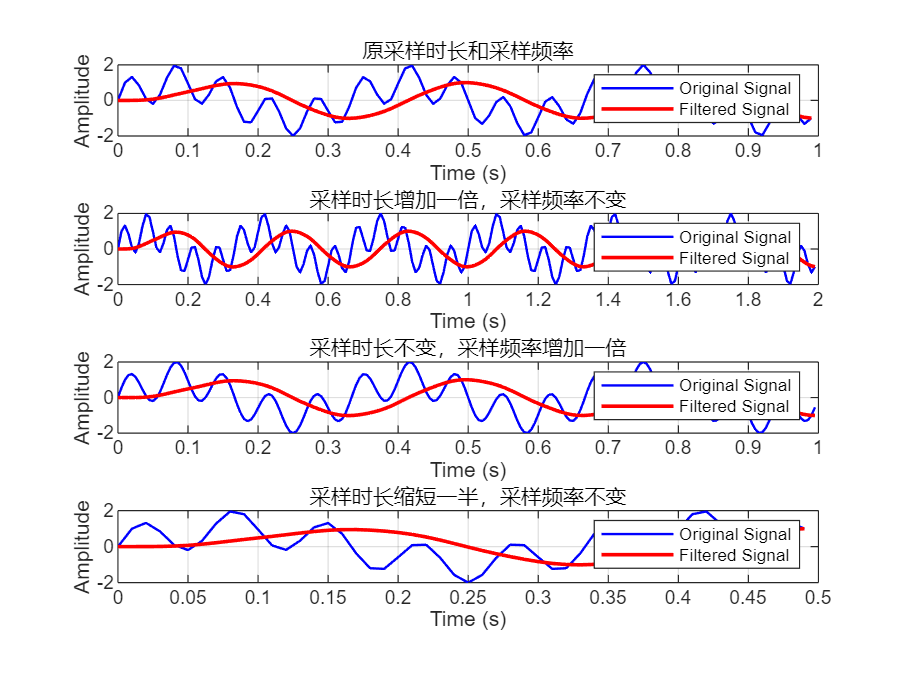

clc;
clear;
close all;

% 参数设置
fs = 100; % 采样频率 (Hz)
T = 1; % 采样时长 (秒)
t = 0:1/fs:T-1/fs; % 时间向量
N = length(t); % 采样点数

% 生成测试信号
f1 = 3; % 通带内频率 (Hz)
f2 = 15; % 阻带内频率 (Hz)
x = sin(2*pi*f1*t) + sin(2*pi*f2*t); % 输入信号

% 滤波器设计
fp = 5; % 通带频率 (Hz)
fs_stop = 10; % 阻带频率 (Hz)
rp = 1; % 通带波动 (dB)
rs = 20; % 阻带衰减 (dB)

% 归一化频率
wp = fp / (fs / 2);
ws = fs_stop / (fs / 2);

% 设计巴特沃斯数字滤波器 (双线性变换法)
[n_butt, wc_butt] = buttord(wp, ws, rp, rs);
[b_butt, a_butt] = butter(n_butt, wc_butt, 'low');

% 滤波
y = filter(b_butt, a_butt, x);

% 时长增加一倍，采样频率不变
T_long = 2 * T; % 新采样时长
t_long = 0:1/fs:T_long-1/fs; % 新时间向量
x_long = sin(2*pi*f1*t_long) + sin(2*pi*f2*t_long); % 新输入信号
y_long = filter(b_butt, a_butt, x_long);

% 时长不变，采样频率增加一倍
fs_high = 2 * fs; % 新采样频率
t_high = 0:1/fs_high:T-1/fs_high; % 新时间向量
x_high = sin(2*pi*f1*t_high) + sin(2*pi*f2*t_high); % 新输入信号
[b_butt_high, a_butt_high] = butter(n_butt, wc_butt / 2, 'low'); % 调整归一化频率
y_high = filter(b_butt_high, a_butt_high, x_high);

% 时长增加一倍，采样频率不变
T_short = 1/2 * T; % 新采样时长
t_short = 0:1/fs:T_short-1/fs; % 新时间向量
x_short = sin(2*pi*f1*t_short) + sin(2*pi*f2*t_short); % 新输入信号
y_short = filter(b_butt, a_butt, x_short);
% 可视化结果
figure;

% 场景 1: 原采样时长和采样频率
subplot(4, 1, 1);
plot(t, x, 'b', 'LineWidth', 1); hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('原采样时长和采样频率');
legend('Original Signal', 'Filtered Signal');
grid on;

% 场景 2: 采样时长增加一倍
subplot(4, 1, 2);
plot(t_long, x_long, 'b', 'LineWidth', 1); hold on;
plot(t_long, y_long, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('采样时长增加一倍，采样频率不变');
legend('Original Signal', 'Filtered Signal');
grid on;

% 场景 3: 采样频率增加一倍
subplot(4, 1, 3);
plot(t_high, x_high, 'b', 'LineWidth', 1); hold on;
plot(t_high, y_high, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('采样时长不变，采样频率增加一倍');
legend('Original Signal', 'Filtered Signal');
grid on;

%场景4：采样时常缩减到原来的一半
subplot(4, 1, 4);
plot(t_short, x_short, 'b', 'LineWidth', 1); hold on;
plot(t_short, y_short, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('采样时长缩短一半，采样频率不变');
legend('Original Signal', 'Filtered Signal');
grid on;